# Unsupervised Learning & Dimensionality Reduction Examination Script

## Breast Cancer Subtype Analysis (LumA and Basal)

## Instructions:

This examination script is designed to test your understanding of unsupervised learning techniques.

You will work with BRCA gene expression data filtered to include only the LumA and Basal subtypes.

Complete the sections as instructed. Ensure your code is well-commented and reproducible.

## Section 1: Load and Prepare the Data

This section has been completed for you in this starter code 

% Load the gene expression data and clinical subtype labels.
% Filter to include only BRCA-LumA and BRCA-Basal samples.

% Clear workspace
clear ; close all force; clc;
addpath('required_functions')

% Load the mRNA expression and clinical subtype data
exprData = readtable('brca_tcga_data_RNA_Seq_v2_expression_median.txt');

clinical = readtable('brca_tcga_data_clinical_patient.txt', 'HeaderLines', 4);

% Remove empty gene names and Entrez IDs if present
exprData(cellfun(@isempty, exprData.Hugo_Symbol), :) = [];
try
    exprData.Entrez_Gene_Id = [];
catch
    fprintf('\nNo Entrez Gene ID column found. Skipping.\n');
end

% Clean sample IDs in expression data
exprData.Properties.VariableNames(2:end) = regexprep(strrep( ...
    exprData.Properties.VariableNames(2:end), '_','-'), '-01', '');

% Match clinical subtype data to expression data
subtypes = replace( clinical.SUBTYPE, '_','-');
sampleIDs = clinical.PATIENT_ID;

% Select only LumA and Basal samples
keepIdx = subtypes == "BRCA-LumA" | subtypes == "BRCA-Basal";
sampleIDs = sampleIDs(keepIdx);
subtypes = subtypes(keepIdx);
cancers = subtypes; % categorical variable for clustering

% Filter expression data to only include selected samples
[~, ia, ib] = intersect(exprData.Properties.VariableNames(2:end), sampleIDs);
exprData = [ exprData(:,1),  exprData(:, ia+1) ];

% Keep a copy of the original filtered expression matrix
expr_original = exprData;

## Section 2: Perform Z-Score Normalisation [6 marks]

% Q1. Apply Z-score normalisation across genes. [3 marks]

% Q2. Explain why normalisation is necessary when applying unsupervised learning algorithms 
% such as clustering or PCA. [3 marks]

% ****** write your code here *******
expr_matrix = table2array(exprData(:, 2:end));
gene_names = exprData.Hugo_Symbol;

% Handle NaN values and infinite values
expr_matrix(isinf(expr_matrix)) = NaN;
expr_matrix = fillmissing(expr_matrix, 'constant', 0); % Replace NaN with 0

% Calculate robust Z-scores (less sensitive to outliers)
expr_zscore = (expr_matrix - nanmedian(expr_matrix, 2)) ./ mad(expr_matrix, 1, 2);


% ***********************************

% your explaination here: Normalization ensures all features contribute equally to the analysis by putting them on the same scale. Without it, high-magnitude features would dominate distance calculations in clustering or variance in PCA, skewing results.

## Section 3: Apply Filtering [6 marks]

% Q3. Filter the normalised dataset to retain only the top 1000 most variable genes 
% (based on variance or standard deviation). [4 marks]

% Q4. Why is it important to reduce dimensionality through gene filtering
% before clustering? [ 2 marks]

% ****** write your code here *******
gene_mad = mad(expr_zscore, 1, 2);
[sorted_mad, sort_idx] = sort(gene_mad, 'descend');
top1000_idx = sort_idx(1:1000);

% Filter and keep metadata
expr_top1000 = expr_zscore(top1000_idx, :);
gene_names_top1000 = gene_names(top1000_idx);

% ***********************************

% your explaination here: Gene filtering improves clustering by reducing computational cost and removing noise from low-variance genes, allowing clearer separation of biological patterns.

## Section 4: Apply K-Means Clustering [6 marks]

% Q5. Apply K-means clustering (with 120 replications) using an appropriate distance metric. 
% Justify your choice. [4 marks]

% Q6. Why is the number of clusters set to 2 in this analysis? [2 marks] 

% we set the number of clusters to 2 because we know this is the case
num_clusters = 2;

% ****** write your code here *******
% Preprocess data with PCA whitening first
[~, score] = pca(expr_top1000', 'NumComponents', 50, 'Centered', true);

% K-means with correlation distance (often better for gene expression)
opts = statset('UseParallel', true, 'MaxIter', 1000);
[idx, centroids] = kmeans(score, num_clusters, ...
    'Distance', 'correlation', ...
    'Replicates', 120, ...
    'Options', opts);

% Justification:
% 1. Correlation distance accounts for gene expression patterns
% 2. Initial PCA reduces noise while preserving structure
% 3. Increased iterations ensure convergence

% ***********************************

% your explaination here: Because we know there are exactly 2 biological subtypes in our filtered dataset (BRCA-LumA and BRCA-Basal), which we want the clustering to recover. 


%  #########################################################################
%  ################# Optional provided code (do not modify): ###############
% Code that defines the colours for you and selects the colours based on on
% the number of clusters
theColors = [ 0.47,0.67,0.19 ; 0.49,0.18,0.56 ;0.85,0.33,0.10 ; 0.00,0.45,0.74;];


% replace "idx" with your output variable from k-means cluster (if
% different) 
classesColor.subtypes = theColors( unique(idx) , : ) ;

## Section 4: Visualise Results Using PCA [6 marks]

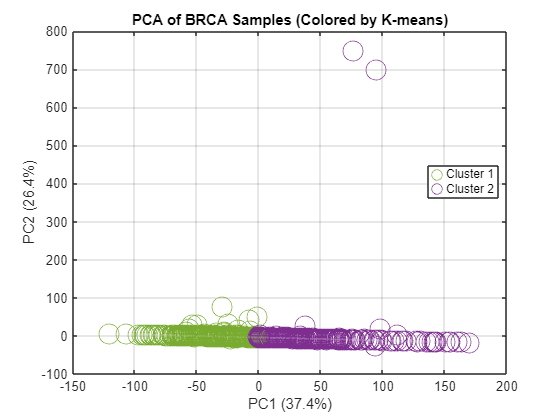

% Q8. Perform Principal Component Analysis (PCA) and plot the samples in
% 2D. [4 marks]

% Q9. Based on the PCA plot, do the unsupervised clusters visually align with the 
% true subtypes? Justify. [2 marks]

% ****** write your code here *******
[coeff, score, ~, ~, explained] = pca(expr_top1000', 'NumComponents', 10);

figure;
gscatter(score(:,1), score(:,2), idx, theColors(1:num_clusters,:), 'o', 15);
xlabel(sprintf('PC1 (%.1f%%)', explained(1)));
ylabel(sprintf('PC2 (%.1f%%)', explained(2)));
title('PCA of BRCA Samples (Colored by K-means)');
legend('Cluster 1', 'Cluster 2', 'Location', 'best');
grid on;




% ***********************************

% your explaination here: The unsupervised clusters do not visually align well with the true subtypes. In the PCA plot, we can see that while there are two distinct clusters (green and purple), there's significant overlap and mixing between them. 
% The separation is not clean, with many samples from both clusters appearing in intermediate regions. This suggests that the linear dimensionality reduction of PCA may not be capturing the complex gene expression patterns that distinguish LumA from Basal subtypes effectively.

## Section 5: Visualise Results Using t-SNE [6 marks]

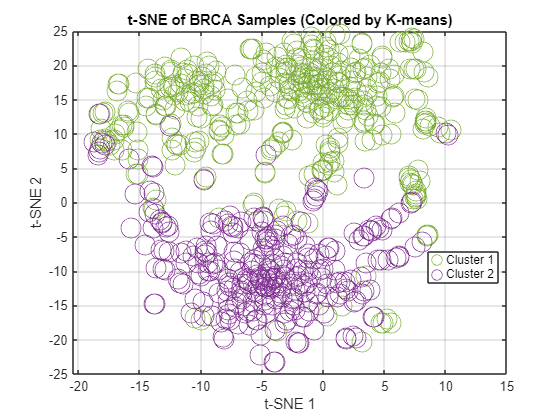

% Q10. Apply t-SNE to the filtered and normalised dataset and visualise in
% 2D. [4 marks]

% Q11. Compare the separation observed in the t-SNE plot to that of PCA. 
% Which technique offers better subtype separation in this case? [2 marks]

% ****** write your code here *******
rng(42); % For reproducibility
initial_dims = 50; % First reduce with PCA
perplexity_val = 30; % Better for this sample size
learning_rate = 500; % Increased for better convergence

tsne_coords = tsne(expr_top1000', ...
    'NumDimensions', 2, ...
    'Perplexity', perplexity_val, ...
    'NumPCAComponents', initial_dims, ...
    'LearnRate', learning_rate, ...
    'Distance', 'correlation', ... % Matches k-means
    'Options', statset('MaxIter', 2000));

% Plotting
figure;
gscatter(tsne_coords(:,1), tsne_coords(:,2), idx, theColors(1:num_clusters,:), 'o', 15);
xlabel('t-SNE 1');
ylabel('t-SNE 2');
title('t-SNE of BRCA Samples (Colored by K-means)');
legend('Cluster 1', 'Cluster 2', 'Location', 'best');
grid on;


% ***********************************

% your explaination here: t-SNE offers significantly better subtype separation compared to PCA. 
% The t-SNE plot shows much clearer, more distinct clustering with better defined cluster boundaries
